# **RBE500: Foundations of Robotics **

# Week 4: Forward Kinematics by Denavit-Hartenberg Parameters

**Kathia Coronado**

*Robotics Engineering Graduate Student, Worcester Polytechnic Institute, Worcester, Massachussets, kcoronado@wpi.edu*

## Introduction

The goal of this assignment was to apply and gain knowledge and experience with the Devanit-Hartenberg (DH) method of obtaining homogeneous transformation matrices (HTM). Devanit-Hartenberg (DH) method is a systematic procedure for computing Forward kinematics (1). It can simplify the analysis of a high degree of freedom manipulator. The DH method represents homogeneous transformation matrices as the product of four basic tranformations. 

**Problem 1**

The first problem of this analysis involves analyzing a three-link cylindrical manipulator, see figure 3.7, by using the DH method to obtain the transformation matrix of the system and then ploting the results. The plot of the system will be animated in order to better understand the system and visualize the forward kinematics.

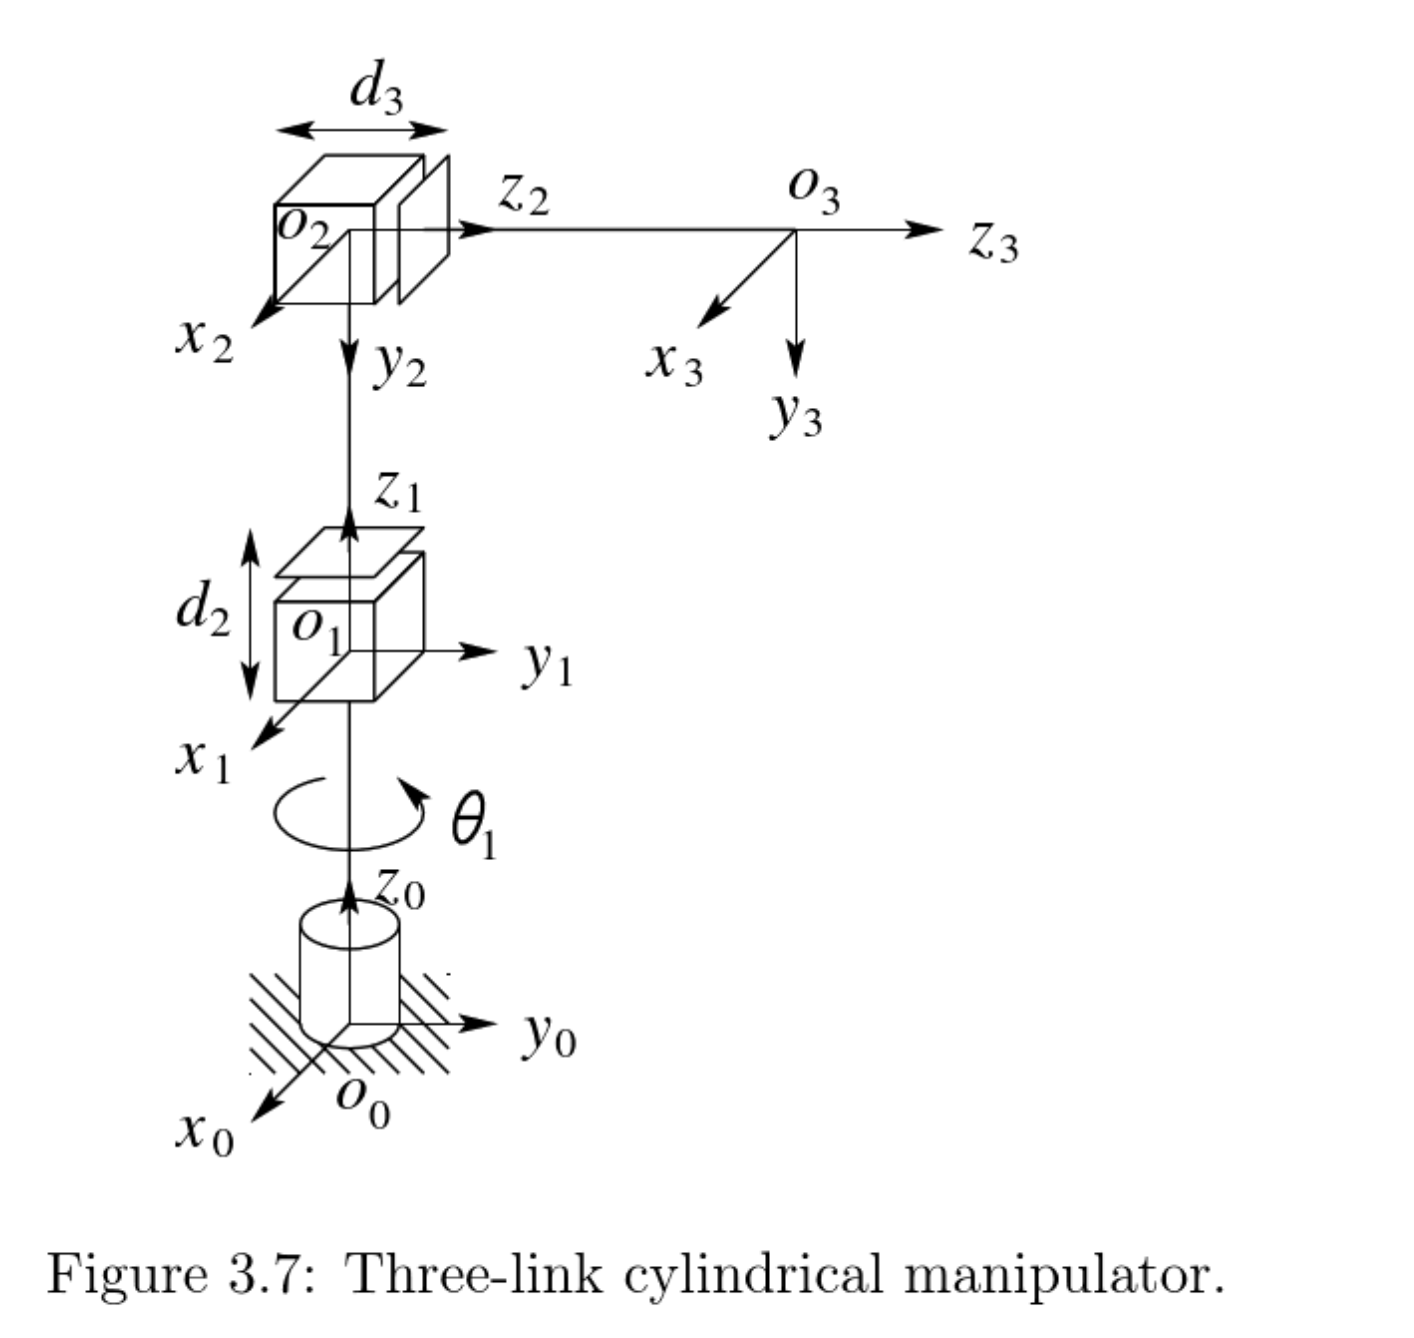

**Problem 2**

The second problem of the assignment involves applying the DH method to a three link articulated robot, see figure 3.16. To accomplish this, the system will be mocked up and labeled in order to denote assumptions. The orientation of the joint variables as well as the assignation of the coordinate frame axes will be chosen arbirarily, but according to the DH method rules.

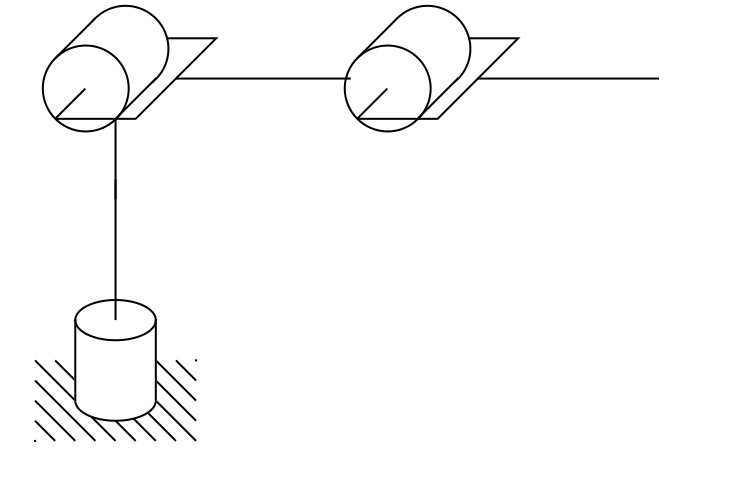

*Figure 3.16 Three-link articulated robot *

**Problem 3**

The third problem of week 4 assignment involves revisiting the Denso HSR robot from week 2 assignment, see figure 1. The system will be  analyzed with the same assumptions as in week 2 analysis, however this time the the HTM will be obtained using the DH method. 

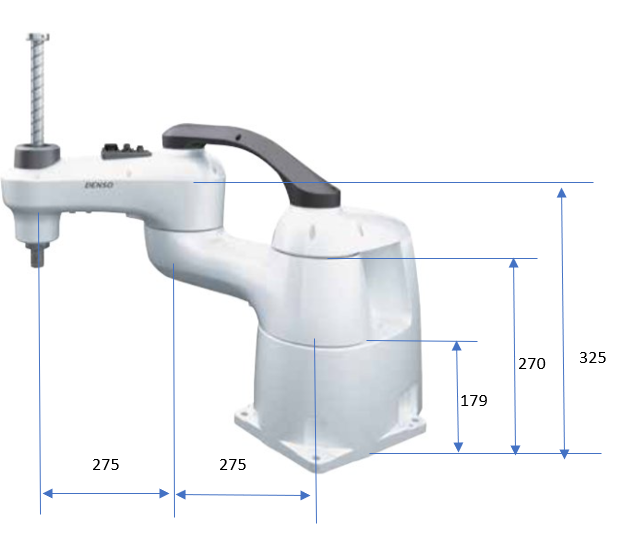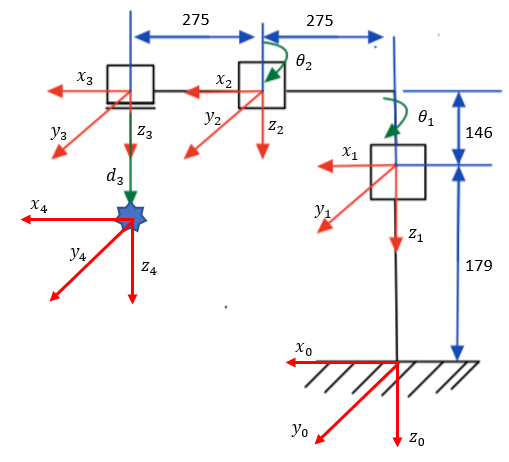

*Figure 1 -  Denso HSR series 480 mm robot with labeled assumed parameters from week 2 assignment*

## Methods and Materials

#### **Problem 1**

**Answer:**

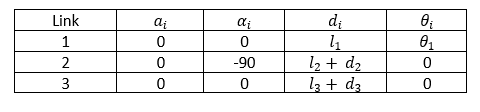


$$H_1^0 =\left(\begin{array}{cccc}
\cos \left(\theta_1 \right) & -\sin \left(\theta_1 \right) & 0 & 0\\
\sin \left(\theta_1 \right) & \cos \left(\theta_1 \right) & 0 & 0\\
0 & 0 & 1 & l_1 \\
0 & 0 & 0 & 1
\end{array}\right)\;$$
 
$$H_2^1 =\left(\begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & -1 & 0 & d_2 +l_2 \\
0 & 0 & 0 & 1
\end{array}\right)\;$$
 
$$H_3^2 =\left(\begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_3 +l_3 \\
0 & 0 & 0 & 1
\end{array}\right)\;$$


T = $\left(\begin{array}{cccc}
\cos \left(\theta_1 \right) & 0 & -\sin \left(\theta_1 \right) & -\sin \left(\theta_1 \right)\,{\left(d_3 +l_3 \right)}\\
\sin \left(\theta_1 \right) & 0 & \cos \left(\theta_1 \right) & \cos \left(\theta_1 \right)\,{\left(d_3 +l_3 \right)}\\
0 & -1 & 0 & d_2 +l_1 +l_2 \\
0 & 0 & 0 & 1
\end{array}\right)$

The first problem of the assignment involves analyzing a three link cylindrical robot, see figure 2.  In order to analyze the system transformation matrices of the system must be obtained. For this analysis, the DH method was used to obtain the tranformation matrices. The DH method simplifies the analysis of a multi link manipulator by representing each HTM, $\,H_i$, as a product of four basic tranformations, see equation 3.10.

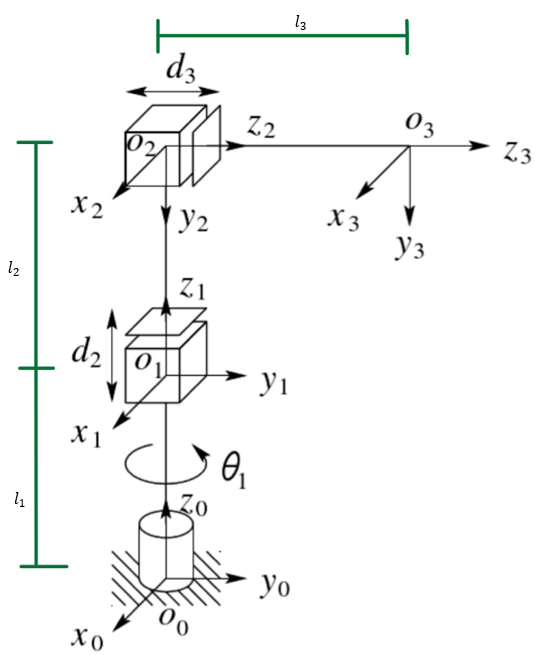

*Figure 2 - labeled diagram of a three link cylindrical robot*

In order to use the DH method, one must first analyze the system and obtain the link length ($a_i$), link twist ($\alpha_i$), link offset ($d_i$) and joint angle ($\theta_i \,$). For this problem these DH parameters were obtained and displayed on table 1.

Table 1- DH parameters for *three link cylindrical robot*

Using these parameters equation 3.10, in the textbook can be used to obtain the homogeneous tranformation matrix for each of the links in the system, see equations 1a-c.

$H_1^0 =\left\lbrack \begin{array}{cccc}
C\theta_1  & -S\theta_1 C\alpha_1  & S\theta_1 S\alpha_1  & a_1 C\theta_1 \\
S\theta_1  & C\theta_1 C\alpha_1  & -C\theta_1 S\alpha_1  & a_1 S\theta_1 \\
0 & S\alpha_1  & C\alpha_1  & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                            (1a)

$H_2^1 =\left\lbrack \begin{array}{cccc}
C\theta_2  & -S\theta_2 C\alpha_2  & S\theta_2 S\alpha_2  & a_2 C\theta_2 \\
S\theta_2  & C\theta_2 C\alpha_2  & -C\theta_2 S\alpha_2  & a_2 S\theta_2 \\
0 & S\alpha_2  & C\alpha_2  & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (1b)

$H_3^2 =\left\lbrack \begin{array}{cccc}
C\theta_3  & -S\theta_3 C\alpha_3  & S\theta_3 S\alpha_3  & a_3 C\theta_3 \\
S\theta_3  & C\theta_3 C\alpha_3  & -C\theta_3 S\alpha_3  & a_3 S\theta_3 \\
0 & S\alpha_3  & C\alpha_3  & d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (1c)

Substituting the DH parameters in equations 1a-1c, with the appropriate and corresponding link parameters in table 1, the homogeneous transformation matrices for each link in the system can be determined, see equation 2a-2c.

$H_1^0 =\left(\begin{array}{cccc}
\cos \left(\theta_1 \right) & -\sin \left(\theta_1 \right) & 0 & 0\\
\sin \left(\theta_1 \right) & \cos \left(\theta_1 \right) & 0 & 0\\
0 & 0 & 1 & l_1 \\
0 & 0 & 0 & 1
\end{array}\right)\;$                                                                                                         (2a)

 $H_2^1 =\left(\begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & -1 & 0 & d_2 +l_2 \\
0 & 0 & 0 & 1
\end{array}\right)\;$                                                                                                                   (2b) 

 $H_3^2 =\left(\begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_3 +l_3 \\
0 & 0 & 0 & 1
\end{array}\right)\;$                                                                                                                     (2c)

Similar to the rules for the compositions of rotation matrices, see equation 2.22, since the second transformation,$H_2^1$, is performed relative to the current frame, then the previous rotation, $H_1^0$, is postmultiplied by the second transformation. third transformation,$H_3^2$, is performed relative to the current frame, then the previous rotation, $H_2^1$, is postmultiplied by the third transformation

the matrices in equation 2a -2c can be post multiplied sequentially to produce the homogeneos tranformation matrix from the base to end effector, $T$, see equation 3

 $T=H_1^0 H_2^1 H_3^2$                                                                                                                                           (3)

Substituting equations 2a-2c into equation 3, the transformation matrix of the system can be obtained, see equation 4. 

T = $\left(\begin{array}{cccc}
\cos \left(\theta_1 \right) & 0 & -\sin \left(\theta_1 \right) & -\sin \left(\theta_1 \right)\,{\left(d_3 +l_3 \right)}\\
\sin \left(\theta_1 \right) & 0 & \cos \left(\theta_1 \right) & \cos \left(\theta_1 \right)\,{\left(d_3 +l_3 \right)}\\
0 & -1 & 0 & d_2 +l_1 +l_2 \\
0 & 0 & 0 & 1
\end{array}\right)$                                                                                  (4)

In order to calculate the position of the robot end eggector with different input angles, the 4th colomn of the tranformation matrix can be extracted. This gives the position vector of the system, see equation 5.

$P_3^0 =$$T$**(:,4)**$=\left\lbrack \begin{array}{c}
-\sin \left(\theta_1 \right)\,{\left(d_3 +l_3 \right)}\\
\cos \left(\theta_1 \right)\,{\left(d_3 +l_3 \right)}\\
d_2 +l_1 +l_2 
\end{array}\right\rbrack$                                                                                                          (5)

#### **Problem 2**

**Answer:**

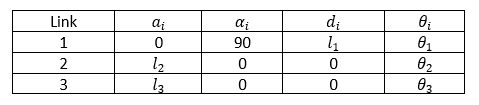


$$H_1^0 =\left(\begin{array}{cccc}
\cos \left(\theta_1 \right) & 0 & \sin \left(\theta_1 \right) & 0\\
\sin \left(\theta_1 \right) & 0 & -\cos \left(\theta_1 \right) & 0\\
0 & 1 & 0 & l_1 \\
0 & 0 & 0 & 1
\end{array}\right)$$
   
$$H_2^1 =$$

$$\left(\begin{array}{cccc}
\cos \left(\,\theta_2 \right) & -\sin \left(\,\theta_2 \right) & 0 & l_2 \,\cos \left(\,\theta_2 \right)\\
\sin \left(\,\theta_2 \right) & \cos \left(\,\theta_2 \right) & 0 & l_2 \,\sin \left(\,\theta_2 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$$
   
$$H_3^2 =\left(\begin{array}{cccc}
\cos \left(\,\theta_3 \right) & -\sin \left(\,\theta_3 \right) & 0 & l_3 \,\cos \left(\,\theta_3 \right)\\
\sin \left(\,\theta_3 \right) & \cos \left(\,\theta_3 \right) & 0 & l_3 \,\sin \left(\,\theta_3 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$$


T = $\left(\begin{array}{cccc}
\cos \left(\theta_2 +\theta_3 \right)\,\cos \left(\,\theta_1 \right) & -\sin \left(\theta_2 +\theta_3 \right)\,\cos \left(\,\theta_1 \right) & \sin \left(\,\theta_1 \right) & \cos \left(\,\theta_1 \right)\,l_3 \,\cos \left(\theta_2 +\theta_3 \right)+l_2 \,\cos \left(\,\theta_2 \right)\\
\cos \left(\theta_2 +\theta_3 \right)\,\sin \left(\,\theta_1 \right) & -\sin \left(\theta_2 +\theta_3 \right)\,\sin \left(\,\theta_1 \right) & -\cos \left(\,\theta_1 \right) & \sin \left(\,\theta_1 \right)l_3 \,\cos \left(\theta_2 +\theta_3 \right)+l_2 \,\cos \left(\,\theta_2 \right)\\
-\sin \left(\theta_2 +\theta_3 \right) & \cos \left(\theta_2 +\theta_3 \right) & 0 & l_1 +l_3 \,\left(-\sin \left(\theta_2 +\theta_3 \right)\right)+l_2 \,\sin \left(\,\theta_2 \right)\\
0 & 0 & 0 & 1
\end{array}\right)$

The second problem of the assignment involves analyzing a three link articulated robot, see figure 3.16. As can be seen in this figure, none of the coordinate frame or variables are labeled for problem. In order to solve the problem, I needed to assign joint variable orientations and coordinate frame vectors to the system. To accomplish this, I used the three DH method rules for assigning coordinate frames listed in section 3.2.2 of the textbook. The labeled diagram of the system is displayed in figure 3.

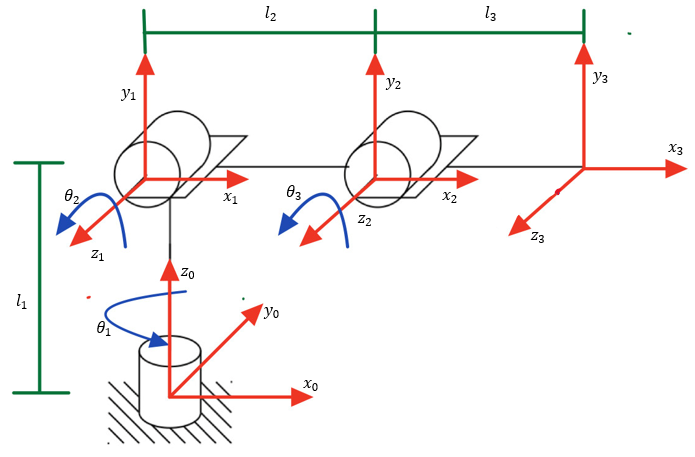

Figure 3 - labeled diagram of a three link articulated robot

 To analyze the system transformation matrices of the system must be obtained. For this analysis, the DH method was used to obtain the tranformation matrices. The DH method simplifies the analysis of a multi link manipulator by representing each HTM, $\,A_i$, as a product of four basic tranformations, see equation 3.10.

In order to use the DH method, one must first analyze the system and obtain the link length ($a_i$), link twist ($\alpha_i$), link offset ($d_i$) and joint angle ($\theta_i \,$). For this problem these DH parameters were obtained and displayed on table 2.

Table 2 - DH parameters for the  three link articulated robot

Using these parameters equation 3.10, in the textbook can be used to obtain the homogeneous tranformation matrix for each of the links in the system, see equations 6a-c.

$H_1^0 =\left\lbrack \begin{array}{cccc}
C\theta_1  & -S\theta_1 C\alpha_1  & S\theta_1 S\alpha_1  & a_1 C\theta_1 \\
S\theta_1  & C\theta_1 C\alpha_1  & -C\theta_1 S\alpha_1  & a_1 S\theta_1 \\
0 & S\alpha_1  & C\alpha_1  & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                            (6a)

$H_2^1 =\left\lbrack \begin{array}{cccc}
C\theta_2  & -S\theta_2 C\alpha_2  & S\theta_2 S\alpha_2  & a_2 C\theta_2 \\
S\theta_2  & C\theta_2 C\alpha_2  & -C\theta_2 S\alpha_2  & a_2 S\theta_2 \\
0 & S\alpha_2  & C\alpha_2  & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (6b)

$H_3^2 =\left\lbrack \begin{array}{cccc}
C\theta_3  & -S\theta_3 C\alpha_3  & S\theta_3 S\alpha_3  & a_3 C\theta_3 \\
S\theta_3  & C\theta_3 C\alpha_3  & -C\theta_3 S\alpha_3  & a_3 S\theta_3 \\
0 & S\alpha_3  & C\alpha_3  & d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (6c)

Substituting the DH parameters in equations 6a-6c, with the appropriate and corresponding link parameters in table 1, the homogeneous transformation matrices for each link in the system can be determined, see equation 7a-7c.

$H_1^0 =\left(\begin{array}{cccc}
\cos \left(\theta_1 \right) & 0 & \sin \left(\theta_1 \right) & 0\\
\sin \left(\theta_1 \right) & 0 & -\cos \left(\theta_1 \right) & 0\\
0 & 1 & 0 & l_1 \\
0 & 0 & 0 & 1
\end{array}\right)$                                                                                                          (7a)

$H_2^1 =$$\left(\begin{array}{cccc}
\cos \left(\,\theta_2 \right) & -\sin \left(\,\theta_2 \right) & 0 & l_2 \,\cos \left(\,\theta_2 \right)\\
\sin \left(\,\theta_2 \right) & \cos \left(\,\theta_2 \right) & 0 & l_2 \,\sin \left(\,\theta_2 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$                                                                                             (7b)

$H_3^2 =\left(\begin{array}{cccc}
\cos \left(\,\theta_3 \right) & -\sin \left(\,\theta_3 \right) & 0 & l_3 \,\cos \left(\,\theta_3 \right)\\
\sin \left(\,\theta_3 \right) & \cos \left(\,\theta_3 \right) & 0 & l_3 \,\sin \left(\,\theta_3 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$                                                                                             (7b)

Similar to the rules for the compositions of rotation matrices, see equation 2.22, since the second transformation,$H_2^1$, is performed relative to the current frame, then the previous rotation, $H_1^0$, is postmultiplied by the second transformation. third transformation,$H_3^2$, is performed relative to the current frame, then the previous rotation, $H_2^1$, is postmultiplied by the third transformation

the matrices in equation 7a -7c can be post multiplied sequentially to produce the homogeneos tranformation matrix from the base to end effector, $T$, see equation 8

 $T=H_1^0 H_2^1 H_3^2$                                                                                                                                           (8)

Substituting equations 2a-2c into equation 3, the transformation matrix of the system can be obtained, see equation 9. 

T = $\left(\begin{array}{cccc}
\cos \left(\theta_2 +\theta_3 \right)\,\cos \left(\,\theta_1 \right) & -\sin \left(\theta_2 +\theta_3 \right)\,\cos \left(\,\theta_1 \right) & \sin \left(\,\theta_1 \right) & \cos \left(\,\theta_1 \right)\,l_3 \,\cos \left(\theta_2 +\theta_3 \right)+l_2 \,\cos \left(\,\theta_2 \right)\\
\cos \left(\theta_2 +\theta_3 \right)\,\sin \left(\,\theta_1 \right) & -\sin \left(\theta_2 +\theta_3 \right)\,\sin \left(\,\theta_1 \right) & -\cos \left(\,\theta_1 \right) & \sin \left(\,\theta_1 \right)l_3 \,\cos \left(\theta_2 +\theta_3 \right)+l_2 \,\cos \left(\,\theta_2 \right)\\
-\sin \left(\theta_2 +\theta_3 \right) & \cos \left(\theta_2 +\theta_3 \right) & 0 & l_1 +l_3 \,\left(-\sin \left(\theta_2 +\theta_3 \right)\right)+l_2 \,\sin \left(\,\theta_2 \right)\\
0 & 0 & 0 & 1
\end{array}\right)$     (9)

In order to calculate the position of the robot end effector with different input angles, the 4th colomn of the tranformation matrix can be extracted. This gives the position vector of the system, see equation 10. 

$P_3^0 =$$T$**(:,4)**$=\left\lbrack \begin{array}{c}
\cos \left(\,\theta_1 \right)\,l_3 \,\cos \left(\theta_2 +\theta_3 \right)+l_2 \,\cos \left(\,\theta_2 \right)\\
\sin \left(\,\theta_1 \right)l_3 \,\cos \left(\theta_2 +\theta_3 \right)+l_2 \,\cos \left(\,\theta_2 \right)\\
l_1 +l_3 \,\left(-\sin \left(\theta_2 +\theta_3 \right)\right)+l_2 \,\sin \left(\,\theta_2 \right)
\end{array}\right\rbrack$                                                                                (10)

This problem required the tracking of each frame relative to zero frame.To do this a similar approach to the above discussion can be implemented. In order to obtain the  position vector of each of the frames relative to the base frame, the fourth column of the  HTM must be extracted, similar to in equation 10. Equation 11a and 11c, display how to obtain the HTM for frame 2 and 0 with respect to frame 0

$H_2^0$= $H_1^0 H_2^1$                                                                                                                                              (11a)

$H_1^0$ = $H_1^0$                                                                                                                                                 (11b)

$H_0^0$ = $R_{z,\,\theta_1 }$                                                                                                                                               (11c)

With these HTM, the position vectors can be obtained for these matrices, similar to equation 10, see equation 12a -12c.

$P_2^0 =H_2^0 \left(:,4\right)$                                                                                                                                            (12a)

$P_2^0 =H_1^0 \left(:,4\right)$                                                                                                                                            (12b)

$P_2^0 =H_0^0 \left(:,4\right)$                                                                                                                                            (12c)

These postion vectors can now be plotted to analyze the motion of each link as the joint variables move.

#### **Problem 3**

**Answer:**

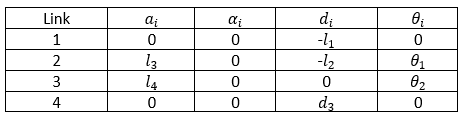


$$H_1^0 =$$

$$\left(\begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & -179\\
0 & 0 & 0 & 1
\end{array}\right)$$
  
$$H_2^1 =$$

$$\left(\begin{array}{cccc}
\cos \left(q_1 \right) & -\sin \left(q_1 \right) & 0 & 275\,\cos \left(q_1 \right)\\
\sin \left(q_1 \right) & \cos \left(q_1 \right) & 0 & 275\,\sin \left(q_1 \right)\\
0 & 0 & 1 & -146\\
0 & 0 & 0 & 1
\end{array}\right)$$
  
$$H_3^2 =$$

$$\left(\begin{array}{cccc}
\cos \left(q_2 \right) & -\sin \left(q_2 \right) & 0 & 275\,\cos \left(q_2 \right)\\
\sin \left(q_2 \right) & \cos \left(q_2 \right) & 0 & 275\,\sin \left(q_2 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$$
  
$$H_4^3 =\;$$

$$\left(\begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & q_3 \\
0 & 0 & 0 & 1
\end{array}\right)$$


T =$\left(\begin{array}{cccc}
\cos \left(\theta_1 +\theta_2 \right) & -\sin \left(\theta_1 +\theta_2 \right) & 0 & 275\,\cos \left(\theta_1 -\theta_2 \right)+275\,\cos \left(\theta_1 \right)\\
\sin \left(\theta_1 +\theta_2 \right) & \cos \left(\theta_1 +\theta_2 \right) & 0 & 275\,\sin \left(\theta_1 -\theta_2 \right)-275\,\sin \left(\theta_1 \right)\\
0 & 0 & 1 & d_3 -325\\
0 & 0 & 0 & 1
\end{array}\right)$

Problem 3, involves analyzing the Denso's HSR robot 480mm 100 mm z-stroke robot. This is a 3 degree of freedom robot. Using the Denso's catalog (2), the links of the robots were approximated to produce a simplified diagram of the model, see figure 1. The coordinate frames, joint angles and link lengths are labeled. The 0th frame represents the base of the robot which has no joint, the 1st, 2nd and 3rd frames represent the 1st, 2nd and 3rd joints, and the 4th frame represents the end effector. 

 To analyze the system transformation matrices of the system must be obtained. For this analysis, the DH method was used to obtain the tranformation matrices. The DH method simplifies the analysis of a multi link manipulator by representing each HTM, $\,A_i$, as a product of four basic tranformations, see equation 3.10.

In order to use the DH method, one must first analyze the system and obtain the link length ($a_i$), link twist ($\alpha_i$), link offset ($d_i$) and joint angle ($\theta_i \,$). For this problem these DH parameters were obtained and displayed on table 3.

Table 3 - DH parameters for DENSO HSR robot

Using these parameters equation 3.10, in the textbook can be used to obtain the homogeneous tranformation matrix for each of the links in the system, see equations 13a-d.

$H_1^0 =\left\lbrack \begin{array}{cccc}
C\theta_1  & -S\theta_1 C\alpha_1  & S\theta_1 S\alpha_1  & a_1 C\theta_1 \\
S\theta_1  & C\theta_1 C\alpha_1  & -C\theta_1 S\alpha_1  & a_1 S\theta_1 \\
0 & S\alpha_1  & C\alpha_1  & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                            (13a)

$H_2^1 =\left\lbrack \begin{array}{cccc}
C\theta_2  & -S\theta_2 C\alpha_2  & S\theta_2 S\alpha_2  & a_2 C\theta_2 \\
S\theta_2  & C\theta_2 C\alpha_2  & -C\theta_2 S\alpha_2  & a_2 S\theta_2 \\
0 & S\alpha_2  & C\alpha_2  & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (13b)

$H_3^2 =\left\lbrack \begin{array}{cccc}
C\theta_3  & -S\theta_3 C\alpha_3  & S\theta_3 S\alpha_3  & a_3 C\theta_3 \\
S\theta_3  & C\theta_3 C\alpha_3  & -C\theta_3 S\alpha_3  & a_3 S\theta_3 \\
0 & S\alpha_3  & C\alpha_3  & d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (13c)

$H_4^3 =\left\lbrack \begin{array}{cccc}
C\theta_4  & -S\theta_4 C\alpha_4  & S\theta_4 S\alpha_4  & a_4 C\theta_4 \\
S\theta_4  & C\theta_4 C\alpha_4  & -C\theta_4 S\alpha_4  & a_4 S\theta_4 \\
0 & S\alpha_4  & C\alpha_4  & d_4 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (13d)

Substituting the DH parameters in equations 13a-13d, with the appropriate and corresponding link parameters in table 1, the homogeneous transformation matrices for each link in the system can be determined, see equation 14a-14c.

$H_1^0 =$$\left(\begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & -179\\
0 & 0 & 0 & 1
\end{array}\right)$                                                                                                                         (14a)

$H_2^1 =$$\left(\begin{array}{cccc}
\cos \left(q_1 \right) & -\sin \left(q_1 \right) & 0 & 275\,\cos \left(q_1 \right)\\
\sin \left(q_1 \right) & \cos \left(q_1 \right) & 0 & 275\,\sin \left(q_1 \right)\\
0 & 0 & 1 & -146\\
0 & 0 & 0 & 1
\end{array}\right)$                                                                                           (14b)  

$H_3^2 =$$\left(\begin{array}{cccc}
\cos \left(q_2 \right) & -\sin \left(q_2 \right) & 0 & 275\,\cos \left(q_2 \right)\\
\sin \left(q_2 \right) & \cos \left(q_2 \right) & 0 & 275\,\sin \left(q_2 \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$                                                                                           (14c)

$H_4^3 =\;$$\left(\begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & q_3 \\
0 & 0 & 0 & 1
\end{array}\right)$                                                                                                                            (14d)

Similar to the rules for the compositions of rotation matrices, see equation 2.22, since the second transformation,$H_2^1$, is performed relative to the current frame, then the previous rotation, $H_1^0$, is postmultiplied by the second transformation. third transformation,$H_3^2$, is performed relative to the current frame, then the previous rotation, $H_2^1$, is postmultiplied by the third transformation

the matrices in equation 14a -14d can be post multiplied sequentially to produce the homogeneos tranformation matrix from the base to end effector, $T$, see equation 15

 $T=H_1^0 H_2^1 H_3^2 H_4^3$                                                                                                                                       (15)

Substituting equations 14a-14d into equation 15, the transformation matrix of the system can be obtained, see equation 16. 

 T =$\left(\begin{array}{cccc}
\mathrm{cos}\left(\theta_1 +\theta_2 \right) & -\mathrm{sin}\left(\theta_1 +\theta_2 \right) & 0 & 275\,\mathrm{cos}\left(\theta_1 -\theta_2 \right)+275\,\mathrm{cos}\left(\theta_1 \right)\\
\mathrm{sin}\left(\theta_1 +\theta_2 \right) & \mathrm{cos}\left(\theta_1 +\theta_2 \right) & 0 & 275\,\mathrm{sin}\left(\theta_1 -\theta_2 \right)-275\,\mathrm{sin}\left(\theta_1 \right)\\
0 & 0 & 1 & d_3 -325\\
0 & 0 & 0 & 1
\end{array}\right)$                                                    (16)

In order to calculate the position of the robot end effector with different input angles, the 4th colomn of the tranformation matrix can be extracted. This gives the position vector of the system, see equation 17. 

$P_3^0 =$$T$**(:,4)**$=\left\lbrack \begin{array}{c}
275\,\mathrm{cos}\left(\theta_1 -\theta_2 \right)+275\,\mathrm{cos}\left(\theta_1 \right)\\
275\,\mathrm{sin}\left(\theta_1 -\theta_2 \right)-275\,\mathrm{sin}\left(\theta_1 \right)\\
d_3 -325
\end{array}\right\rbrack$                                                                                         (17)

## Results

#### **Problem 1** 

Define symbolic variable and link lengths 

clc; clear ;
syms theta_1 d_2 d_3 l_1 l_2 l_3

DH parameters for the system :

a = [0;0;0];
alpha = [0;-90;0];
d = [l_1 ; l_2+d_2 ; l_3 + d_3];
theta = [ theta_1 ; 0 ; 0];

Call out function that uses DH parameters to find the homogeneous transformation matrix using the the DH method. Below are the sequential homogeneous transformation matrices for the system.

A= GetDH(a, alpha, d, theta);
H01=A{1}

$$H01 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & 0\\ \sin\left(\frac{\pi \,\theta_{1}}{180}\right) & \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & 0\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H12=A{2}

$$H12 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & d_{2}+l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H23=A{3}

$$H23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{3}+l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Call the function that calculates the transformation matrix for the system from the base of the system to the end effector.

T= getT(A)

$$T = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & -\sin\left(\frac{\pi \,\theta_{1}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\,\left(d_{3}+l_{3}\right)\\ \sin\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & \cos\left(\frac{\pi \,\theta_{1}}{180}\right)\,\left(d_{3}+l_{3}\right)\\ 0 & -1 & 0 & d_{2}+l_{1}+l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

subtitute the length of 1 mm as the link lengths for the system, this will simbolically replace them.

T_sub = subs(T, {l_1,l_2,l_3},{1,1,1});    

Plot the position of the end effector with repect to the base, for joint one moving from 0 to 180 degrees

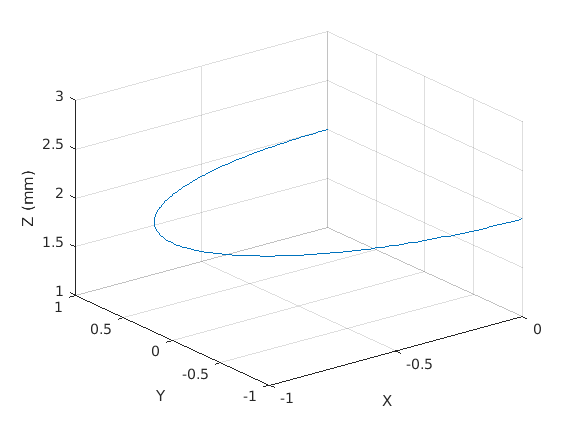

q1t= 0:1:180;
q2t =0;
q3t = 0;

q= {theta_1,d_2,d_3};
qt= {q1t,q2t,q3t};

plotee(T_sub, q, qt);

*Plot 1: Joint 1 varying from 0 to 180 deg *

Plot the position of the end effector with repect to the base, for joint two moving from 0 to 0.1m 

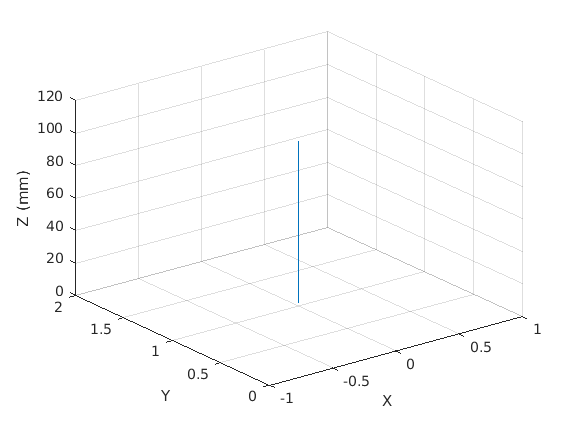

q1t= 0;
q2t= 0:(100/180):100;
q3t = 0;

q= {theta_1,d_2,d_3};
qt= {q1t,q2t,q3t};

plotee(T_sub, q, qt);

*Plot 2: Joint 2 varying from 0 to 100mm*

Plot the position of the end effector with repect to the base, for joint three moving from 0 to 0.1m. 

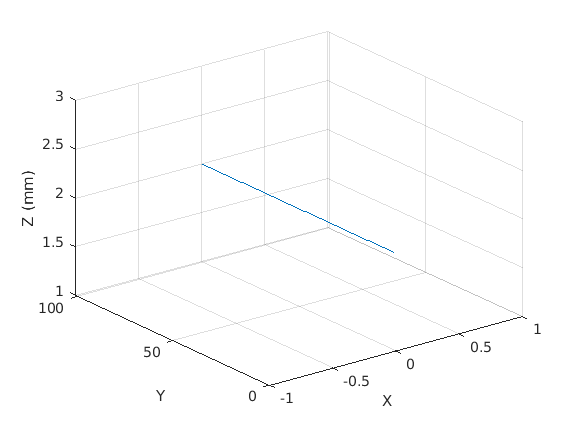

q1t= 0;
q2t= 0;
q3t= 0:(100/180):100;

q= {theta_1,d_2,d_3};
qt= {q1t,q2t,q3t};

plotee(T_sub, q, qt);

*Plot 3: Joint 3 varying from 0 to 100mm*

#### **Problem 2**

Define symbolic variable and link lengths :

clc;clear;
syms theta_1 theta_2 theta_3 l_1 l_2 l_3

DH parameters for the system :

a = [0; l_2; l_3];
alpha = [90;0;0];
d = [l_1;0;0];
theta = [theta_1; theta_2; theta_3];

Call out function that uses DH parameters to find the homogeneous transformation matrix using the the DH method. Below are the sequential homogeneous transformation matrices for the system.

A = GetDH(a, alpha, d, theta);
H01=A{1}

$$H01 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & \sin\left(\frac{\pi \,\theta_{1}}{180}\right) & 0\\ \sin\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & -\cos\left(\frac{\pi \,\theta_{1}}{180}\right) & 0\\ 0 & 1 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H12=A{2}

$$H12 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{2}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{2}}{180}\right) & 0 & l_{2}\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sin\left(\frac{\pi \,\theta_{2}}{180}\right) & \cos\left(\frac{\pi \,\theta_{2}}{180}\right) & 0 & l_{2}\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H23=A{3}

$$H23 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{3}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{3}}{180}\right) & 0 & l_{3}\,\cos\left(\frac{\pi \,\theta_{3}}{180}\right)\\ \sin\left(\frac{\pi \,\theta_{3}}{180}\right) & \cos\left(\frac{\pi \,\theta_{3}}{180}\right) & 0 & l_{3}\,\sin\left(\frac{\pi \,\theta_{3}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Call the function that calculates the transformation matrix for the system from the base of the system to the end effector.

T = simplify(getT(A))  

$$T = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{5}\,\sigma_{3} & -\sigma_{1}\,\sigma_{3} & \sigma_{2} & \sigma_{3}\,\sigma_{4}\\ \sigma_{5}\,\sigma_{2} & -\sigma_{1}\,\sigma_{2} & -\sigma_{3} & \sigma_{2}\,\sigma_{4}\\ \sigma_{1} & \sigma_{5} & 0 & l_{1}+l_{3}\,\sigma_{1}+l_{2}\,\sin\left(\frac{\pi \,\theta_{2}}{180}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,\theta_{1}}{180}\right)\\ \sigma_{4}=l_{3}\,\sigma_{5}+l_{2}\,\cos\left(\frac{\pi \,\theta_{2}}{180}\right)\\ \sigma_{5}=\cos\left(\frac{\pi \,\left(\theta_{2}+\theta_{3}\right)}{180}\right) \end{array}$$

subtitute the length of 1 mm as the link lengths for the system, this will simbolically replace them.

T_sub = subs(T, {l_1,l_2,l_3},{1,1,1});  

Plot the position of the end effector with repect to the base, for the given interval 

q1t= 0:1:180;
q2t= 0:1:180;
q3t= 0:1:180;
q= {theta_1,theta_2,theta_3};
qt= {q1t,q2t,q3t};

Plot from frame 0 to 3

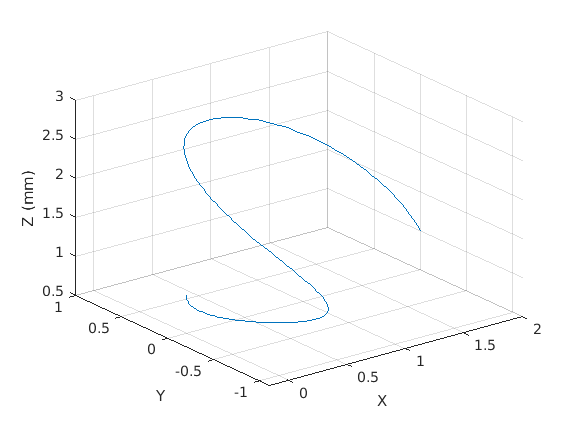


plotee(T_sub, q, qt);

*Plot 4: Position of end effector relative to base with varying joint angles*

Plot from frame 0 to 2. Link lengths are 1 mm.

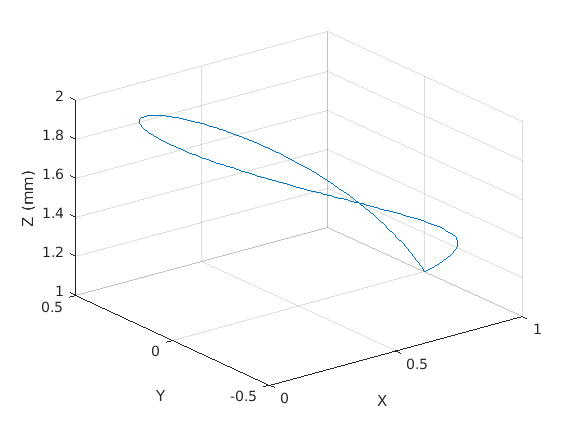


T02 = subs(H01*H12, {l_1,l_2,l_3},{1,1,1});  
plotee(T02, q, qt);

*Plot 5: Position of joint 2 relative to base with varying joint angles*

Plot from frame 0 to 1. Link lengths are 1 mm

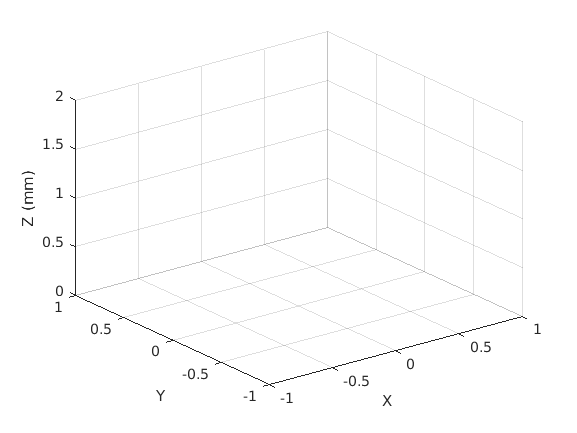


T01 = subs(H01, {l_1,l_2,l_3},{1,1,1});  
plotee(T01, q, qt);

*Plot 6: Position of joint 1 relative to base with varying joint angles*

the transformation matrix of frame 0 with repect to frame 0 is just the rotation matrix produce by rotating frame 0 by $\,\theta_1$.

Plot from frame 0 to 0. Link lengths are 1 mm


T00= [cosd(theta_1) -sind(theta_1) 0 0; sind(theta_1) cosd(theta_1) 0 0; 0 0 1 0;0 0 0 1];
T00_sub = subs(T00,{l_1,l_2,l_3},{1,1,1})

$$T00\_sub = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & -\sin\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & 0\\ \sin\left(\frac{\pi \,\theta_{1}}{180}\right) & \cos\left(\frac{\pi \,\theta_{1}}{180}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

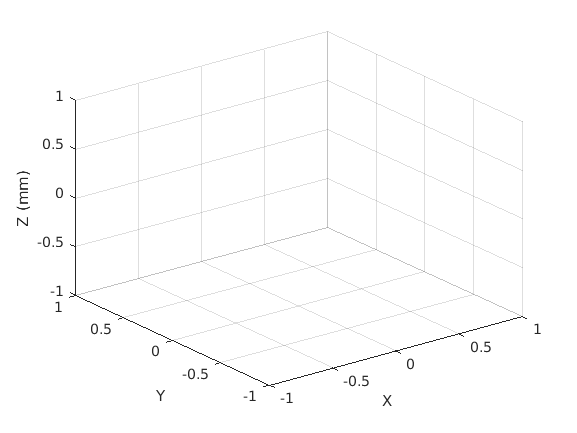

plotee(T00_sub, q, qt);

*Plot 7: Position of base relative to base with varying joint angles*

#### Problem 3

Define symbolic variable and link lengths 

clc;clear;
syms q1 q2 q3 
l1= 179;
l2= 146;
l3= 275;
l4= 275;

DH parameters for the system 

a = [0; l3; l4; 0];
alpha = [0;0;0;0];
d = [-l1;-l2;0; q3];
theta = [0;q1; q2; 0];

Call out function that uses DH parameters to find the homogeneous transformation matrix using the the DH method. Below are the sequential homogeneous transformation matrices for the system.

A = GetDH(a, alpha, d, theta);
H01 = A{1}

$$H01 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & -179\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H12 = A{2}

$$H12 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{1}}{180}\right) & -\sin\left(\frac{\pi \,q_{1}}{180}\right) & 0 & 275\,\cos\left(\frac{\pi \,q_{1}}{180}\right)\\ \sin\left(\frac{\pi \,q_{1}}{180}\right) & \cos\left(\frac{\pi \,q_{1}}{180}\right) & 0 & 275\,\sin\left(\frac{\pi \,q_{1}}{180}\right)\\ 0 & 0 & 1 & -146\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H23 = A{3}

$$H23 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{2}}{180}\right) & -\sin\left(\frac{\pi \,q_{2}}{180}\right) & 0 & 275\,\cos\left(\frac{\pi \,q_{2}}{180}\right)\\ \sin\left(\frac{\pi \,q_{2}}{180}\right) & \cos\left(\frac{\pi \,q_{2}}{180}\right) & 0 & 275\,\sin\left(\frac{\pi \,q_{2}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H34 = A{4}

$$H34 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & q_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Call the function that calculates the transformation matrix for the system from the base of the system to the end effector.

T= getT(A);
simplify(T)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & 275\,\sigma_{2}+275\,\cos\left(\frac{\pi \,q_{1}}{180}\right)\\ \sigma_{1} & \sigma_{2} & 0 & 275\,\sigma_{1}+275\,\sin\left(\frac{\pi \,q_{1}}{180}\right)\\ 0 & 0 & 1 & q_{3}-325\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(q_{1}+q_{2}\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\left(q_{1}+q_{2}\right)}{180}\right) \end{array}$$

plot the end effector with respect to the base.

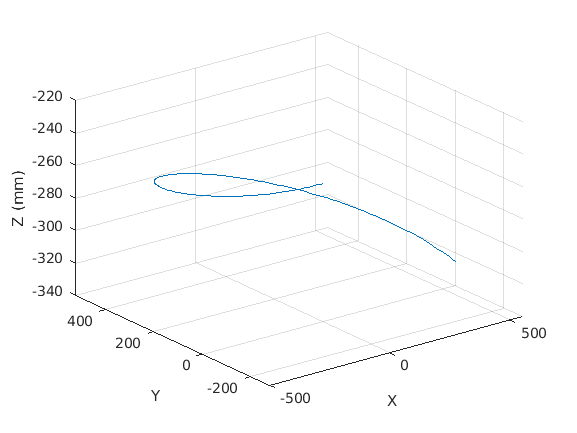

q1t= 0:1:180;
q2t= 0:1/2:90;
q3t= 0:(100/180):100;
q= {q1,q2,q3};
qt= {q1t,q2t,q3t};

plotee(T, q, qt);

Plot 8: Position of Denso HSR end effector relative to base with varying joint variables

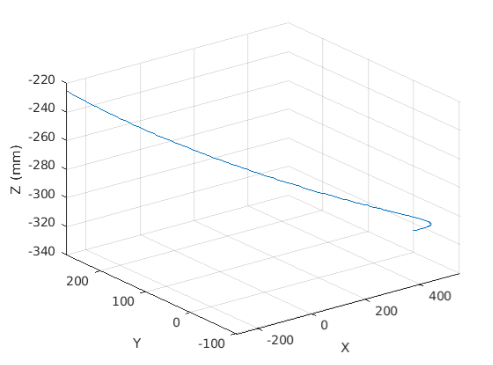

Plot 9: Week 2 position of DENSO HSR end effector relative to base with varying joint variables

#### **Functions**

This function uses the DH parameter to calculated the HTM using the DH method. This function will work for any number of joints. The output of this function is a cell array 

function A = GetDH (a, alpha,d,theta)
A = {};
for i = (1:length(a))
    
    H = [ cosd(theta(i)) -sind(theta(i))*cosd(alpha(i)) sind(theta(i))*sind(alpha(i)) a(i)*cosd(theta(i));
         sind(theta(i)) cosd(theta(i))*cosd(alpha(i)) -cosd(theta(i))*sind(alpha(i)) a(i)*sind(theta(i));
         0 sind(alpha(i)) cosd(alpha(i)) d(i);
         0 0 0 1];
    A{i}= H;
end
end

The purpose of this function is to get the tranformation matrix of the end effector with respect to the base. The input of this function is a cell array of all of the homogeneous tranformation matrices of the system in order. This will work for systems with any number of joints.

function T= getT(A)

T= eye(4);
for j = (1: length(A(:,:,1)))
    T= T * A{j};
end
end

The purpose of this function is to plot the effector of a system with repect to the base. The output of this function is a 3D plot. The input of this frunction is the transformation matrix, cell array of the system's symbolic joint variables and a cell array of the intervals one would like to sub in for the joint variables.

function plotee(T,q,qt)
pe = expand(T(1:3,4));
pe_simp= simplify(pe);
x=pe_simp(1);
y=pe_simp(2);
z=pe_simp(3);

x_plot= subs(x,q,qt);
y_plot= subs(y,q,qt);
z_plot=subs(z,q,qt);
figure()
plot3(x_plot,y_plot,z_plot);
grid on
xlabel('X ')
ylabel('Y ')
zlabel('Z (mm)')

end

## **DIscussion**

All three problems of this assigment involved using DH parameters method to analyze a robotic system.Problem 1 allowed me to analyze a three link cylindrical robot, this problem was interesting in that it required tracking of the all of the links, not just the end effector. To accomplish this, I used the DH method to obtain the HTM for all of the links and then multiplied them in the appropriate order to obtain the transformation matrix of the end effector with respect to the base of the robot. Once I did this, I plotted the position vector of the transformation for varying joint variables sequentially, see plots 1 - plot 3. Viewing these plots they look correct. In plot 1, when i only moved joint 1, which is revolute, the trajectory was a loop from 0 to 180 degrees. In plot 2,  I only moved prismatic joint 2, which moves up and down, the trajectory was a verticle line. In plot 3, I only moved joint 3,a horizontally orientated prismatic joint, the plot displayed a horizontal line.

Problem 2, was similar to problem 1 in that it required DH method to obtain HTMs for analysis, however, the diagram of this problem was not labeled. This created the opportunity for me to assignment my own joint variables and frame coordinates using the rules for assigning coordinate frames, mentioned in the textbook. Assigning my own coordinate frames was my favorite part of this assignment, as it gave me freedom and allowed me to think ahead and imagine how different frame orientations can affect my solution. Once I assigned the variable directions and frames, I calculated the homogeneous transformation matrices and then plotted the trajectory of each frame with respect to the base frame, see plots 4 - plot 7. Looking at these plots, they look to be correct. With varying joint angles, frames 3 and 2 with respect to frame 0 experience many loops, see plots 4 and 5. Plots 6 and 7, displayed no trajectory as  the position of frame 0 and frame 1 do not change with varying joint angles.

Problem 3 allowed me to revisit the DENSO HSR robot, that was analyzed in week 2. For this problem I also used the DH method to obtain HTM. I then plotted the position vectory of the robot, see plot 8, in order to compare this solution to the one I obtained in week 2, see plot 9. After comparing the two plots, i notices that they were similar but varied a bit. This indicates that atleast one of my solutions is incorrect.

This assignment was very interesting and challenging, It involved a new method of obtaining HTM and also put my matlab skills to the test. The assignment allowed me to learn about gain experience in using DH parameter method for HTM. As I have never used DH method, there was a bit of a learning curve, however I was able to learn and appreciate it. The most challenging part of this assignment for me was researching about how to use matlab for animations. I am still working towards figuring that out.

### References:

(1) Spong et al. (2020).* Robot Modeling and Control *(2nd Edition). Wiley.